# Code for Exploratory data analysis

# Import data from csv file

Script for importing data from the following text file:

Auto-generated by MATLAB on 09-Jun-2020 11:23:13

%Clear all the data
clear

## Setup the Import Options and import the data






% Import the data
t1= readtable("C:\Users\HP\Desktop\Data csv\India_total.csv" );
t2= readtable("C:\Users\HP\Desktop\Data csv\Kerala_Cases.csv");
t3= readtable("C:\Users\HP\Desktop\Data csv\Kerala_Cases_II_Phase.csv");
t4= readtable("C:\Users\HP\Desktop\Data csv\Kerala_Cases_India_Cases_merged.csv");

t5= readtable("C:\Users\HP\Desktop\Data csv\kerala_Community_Kitchen.csv");
t6= readtable("C:\Users\HP\Desktop\Data csv\kerala_Deaddiction.csv");

t7= readtable("C:\Users\HP\Desktop\Data csv\kerala_Deaths.csv");
t8= readtable("C:\Users\HP\Desktop\Data csv\kerala_discomfort.csv");


t10= readtable("C:\Users\HP\Desktop\Data csv\kerala_expenditure.csv");

t11= readtable("C:\Users\HP\Desktop\Data csv\Kerala_hotspot.csv");

t12= readtable("C:\Users\HP\Desktop\Data csv\kerala_quarantine.csv");

t14= readtable("C:\Users\HP\Desktop\Data csv\Kerala_Testing.csv");
t15= readtable("C:\Users\HP\Desktop\Data csv\Kerala_Transmission.csv");
t16= readtable("C:\Users\HP\Desktop\Data csv\Kerala_volunt_agegroup.csv");

t17= readtable("C:\Users\HP\Desktop\Data csv\kerala_volunteer_category.csv");

t18= readtable("C:\Users\HP\Desktop\Data csv\kerala_volunteer_operation.csv");

%Convert soem variables to categorical
t16.AgeGroup=categorical(t16.AgeGroup);
t17.Category=categorical(t17.Category);
t18.Category=categorical(t18.Category);
t11.District=categorical(t11.District);
t8.District_=categorical(t8.District_);
t6.District_=categorical(t6.District_);

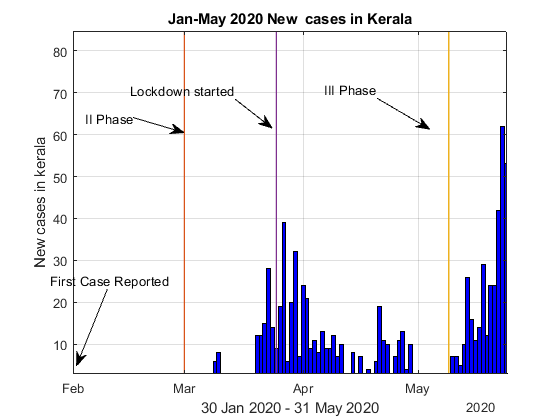

%Jan-May 2020 New Cases in kerala
bar(t2.Date,t2.New_Cases,1,"grouped","blue")
t1mark=datetime(2020,03,01);
hold on

plot([t1mark t1mark], ylim,"LineWidth",1);
t2mark=datetime(2020,05,09);
plot([t2mark t2mark], ylim,"LineWidth",1);
t3mark=datetime(2020,03,25);
plot([t3mark t3mark], ylim,"LineWidth",1);

xlim([datetime(2020,1,31,22,17,38)...
      datetime(2020,5,24,4,50,21)])
ylim([2.9 84.7])
grid on
title('Jan-May 2020 New  cases in Kerala')
xlabel('30 Jan 2020 - 31 May 2020')
ylabel('New cases in kerala')
annotation('textarrow',[0.6735 0.7673],[0.766 0.6925],'String','III Phase')
annotation('textarrow',[0.4204 0.4857],[0.7633 0.6952],'String','Lockdown started')
annotation('textarrow',[0.2388 0.3286],[0.7197 0.6844],'String','II Phase')
annotation('textarrow',[0.1918 0.1367],[0.3116 0.1293],'String','First Case Reported')
hold off

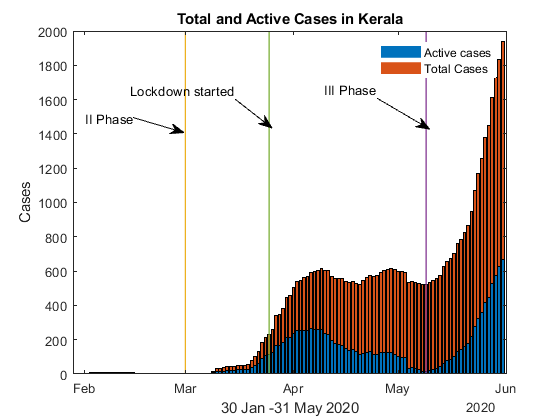

%Total and Active cases in kerala
a= [t2.Date];
b=[t2.Active_Cases,t2.Total_Cases];
bar(a,b,'stacked',"FaceColor","flat")
hold on
t1mark=datetime(2020,03,01);
plot([t1mark t1mark], ylim,"LineWidth",1);
t2mark=datetime(2020,05,09);
plot([t2mark t2mark], ylim,"LineWidth",1);
t3mark=datetime(2020,03,25);
plot([t3mark t3mark], ylim,"LineWidth",1);
annotation('textarrow',[0.4204 0.4857],[0.7633 0.6952],'String','Lockdown started');
annotation('textarrow',[0.2388 0.3286],[0.7197 0.6844],'String','II Phase');annotation('textarrow',[0.6735 0.7673],[0.766 0.6925],'String','III Phase');
title('Total and Active Cases in Kerala');
xlabel('30 Jan -31 May 2020');
ylabel('Cases');
legend("Active cases","Total Cases")
hold off

% Recovered cases and deaths
c=[t2.Recovered_Cases,t2.new_death];

c =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


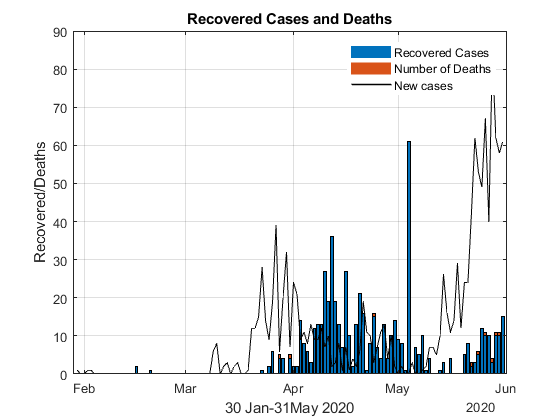

bar(a,c,'stacked')
hold on
plot(a,t2.New_Cases,"LineWidth",1,"Color",[0 0 0])
legend("Recovered Cases","Number of Deaths","New cases")
hold off

title('Recovered Cases and Deaths')
xlabel('30 Jan-31May 2020')
ylabel('Recovered/Deaths')

grid on

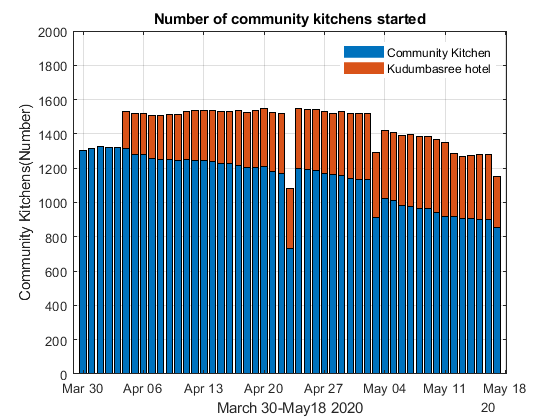



%Number of community kitchen started
t5 = sortrows(t5,'Date');
d=[t5.Date];
e=[t5.Total_ck,t5.Kudumb_hotels];
bar(d,e,'stacked',"BarWidth",0.75)
ylim([0 2000])

grid on
title('Number of community kitchens started')
xlabel('March 30-May18 2020')
ylabel('Community Kitchens(Number)')
legend("Community Kitchen","Kudumbasree hotel")

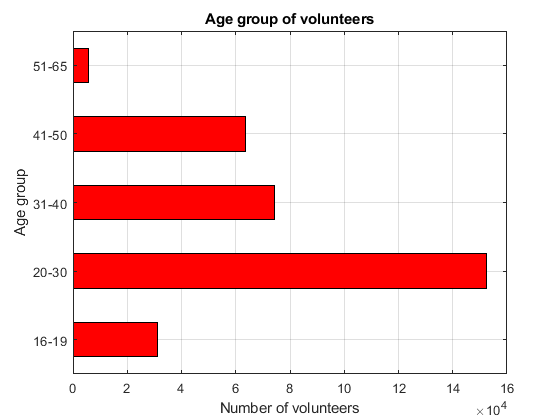


%Age group of volunteers
barh(t16.AgeGroup,t16.NoOfVolunteers,"red","BarWidth",0.5)

grid on

title('Age group of volunteers')
xlabel('Number of volunteers')
ylabel('Age group')

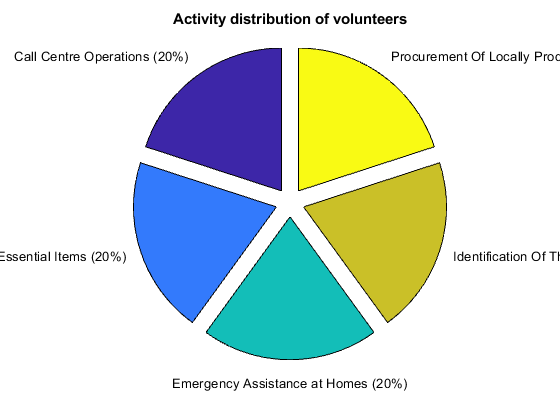

%Activity distribution of volunteers
pie(t17.Category,t17.Count)
title('Activity distribution of volunteers')

%Work carried out by volunteers
t18

t18 = 5×3 table
    SlNo               Category                 Count   
    ____    ______________________________    __________

     1      Control Room Operations                51027
     2      Relief Work                       1.3443e+05
     3      Delivery Of Materials To Camps    1.1815e+05
     4      Communicating Alerts                   85316
     5      Help in Hospitals                 1.2417e+05


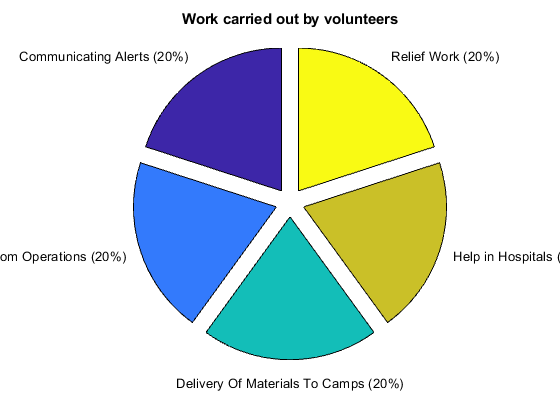

pie(t18.Category,t18.Count)
title("Work carried out by volunteers")

%Home quarantine details during Phase II
t12

t12 = 123×4 table
       Date       tot_hospital    Home_quar    new_hospital
    __________    ____________    _________    ____________

    01/30/2020         0              0             0      
    01/31/2020         0              0             0      
    02/01/2020         0              0             0      
    02/02/2020         0              0             0      
    02/03/2020         0              0             0      
    02/04/2020         0              0             0      
    02/05/2020         0              0             0      
    02/06/2020         0              0             0      
    02/07/2020         0              0             0      
    02/08/2020         0              0             0      
    02/09/2020         0              0             0      
    02/10/2020         0              0             0      
    0

f=[t12.Date];

f = 123×1 datetime array
   01/30/2020
   01/31/2020
   02/01/2020
   02/02/2020
   02/03/2020
   02/04/2020
   02/05/2020
   02/06/2020
   02/07/2020
   02/08/2020
   02/09/2020
   02/10/2020
   02/11/2020
   02/12/2020
   02/13/2020
   02/14/2020
   02/15/2020
   02/16/2020
   02/17/2020
   02/18/2020
   02/19/2020
   02/20/2020
   02/21/2020
   02/22/2020
   02/23/2020
   02/24/2020
   02/25/2020
   02/26/2020
   02/27/2020
   02/28/2020


g=[t12.Home_quar];

g =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


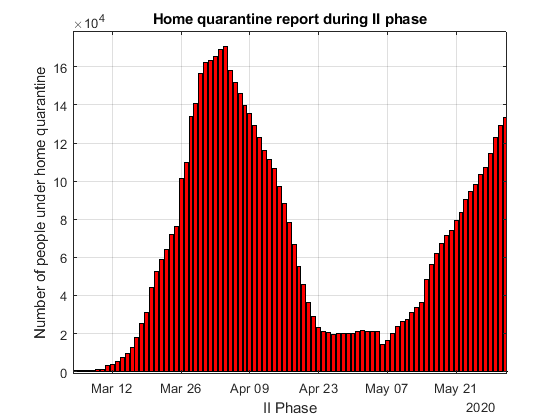

bar(f,g,"red")
xlim([datetime(2020,3,3,23,19,60)...
      datetime(2020,5,31,8,55,60)])
ylim([-1200 178800])

grid on
title('Home quarantine report during II phase')
xlabel('II Phase')
ylabel('Number of people under home quarantine')

%New hospital admissions with covid symptoms
t12;

t12 = 123×4 table
       Date       tot_hospital    Home_quar    new_hospital
    __________    ____________    _________    ____________

    01/30/2020         0              0             0      
    01/31/2020         0              0             0      
    02/01/2020         0              0             0      
    02/02/2020         0              0             0      
    02/03/2020         0              0             0      
    02/04/2020         0              0             0      
    02/05/2020         0              0             0      
    02/06/2020         0              0             0      
    02/07/2020         0              0             0      
    02/08/2020         0              0             0      
    02/09/2020         0              0             0      
    02/10/2020         0              0             0      
    0

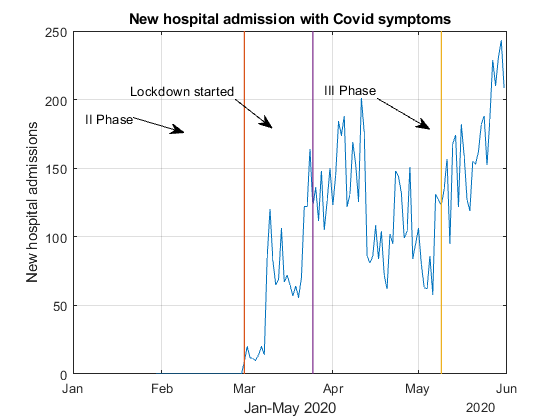

plot(t12.Date,t12.new_hospital)
hold on
t1mark=datetime(2020,03,01);
plot([t1mark t1mark], ylim,"LineWidth",1);
t2mark=datetime(2020,05,09);
plot([t2mark t2mark], ylim,"LineWidth",1);
t3mark=datetime(2020,03,25);
plot([t3mark t3mark], ylim,"LineWidth",1);
annotation('textarrow',[0.4204 0.4857],[0.7633 0.6952],'String','Lockdown started');
annotation('textarrow',[0.2388 0.3286],[0.7197 0.6844],'String','II Phase');annotation('textarrow',[0.6735 0.7673],[0.766 0.6925],'String','III Phase');
grid on
title('New hospital admission with Covid symptoms')
xlabel('Jan-May 2020')
ylabel('New hospital admissions')


hold off

%Testing done per day - Kerala
t14;

t14 = 123×3 table
       date       test_kerala    test_kerala_per_thousand
    __________    ___________    ________________________

    01/30/0020         0                    0            
    01/31/0020         0                    0            
    02/01/0020         0                    0            
    02/02/0020         0                    0            
    02/03/0020         0                    0            
    02/04/0020         0                    0            
    02/05/0020         0                    0            
    02/06/0020         0                    0            
    02/07/0020         0                    0            
    02/08/0020         0                    0            
    02/09/0020         0                    0            
    02/10/0020         0                    0            
    02/11/0020         0                    0            
    02/12

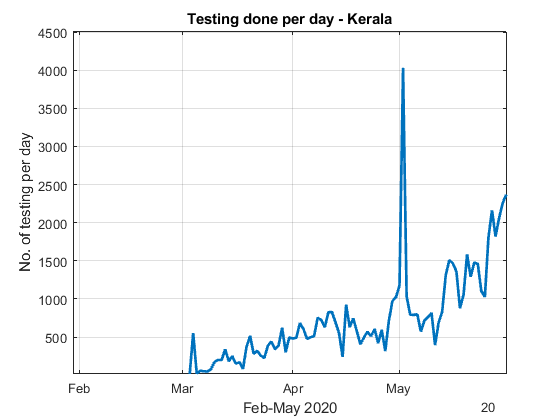

plot(t14.date,t14.test_kerala,"LineWidth",2)

xlim([datetime(20,1,30,5,15,41)...
      datetime(20,5,31,5,15,41)])
ylim([15 4515])
title('Testing done per day - Kerala')
xlabel('Feb-May 2020')
ylabel('No. of testing per day')
grid on

%Covid-19 cases-type-Kerala
t15;

t15 = 123×3 table
       Date       Travel    Person_to_Person
    __________    ______    ________________

    01/30/2020      1              0        
    01/31/2020      0              0        
    02/01/2020      0              0        
    02/02/2020      1              0        
    02/03/2020      1              0        
    02/04/2020      0              0        
    02/05/2020      0              0        
    02/06/2020      0              0        
    02/07/2020      0              0        
    02/08/2020      0              0        
    02/09/2020      0              0        
    02/10/2020      0              0        
    02/11/2020      0              0        
    02/12/2020      0              0        
    02/13/2020      0              0        
    02/14/2020      0              0        


j=[t15.Date];

j = 123×1 datetime array
   01/30/2020
   01/31/2020
   02/01/2020
   02/02/2020
   02/03/2020
   02/04/2020
   02/05/2020
   02/06/2020
   02/07/2020
   02/08/2020
   02/09/2020
   02/10/2020
   02/11/2020
   02/12/2020
   02/13/2020
   02/14/2020
   02/15/2020
   02/16/2020
   02/17/2020
   02/18/2020
   02/19/2020
   02/20/2020
   02/21/2020
   02/22/2020
   02/23/2020
   02/24/2020
   02/25/2020
   02/26/2020
   02/27/2020
   02/28/2020


k=[t15.Travel,t15.Person_to_Person];

k =      1     0
     0     0
     0     0
     1     0
     1     0
     0     0
     0     0
     0     0
     0     0
     0     0


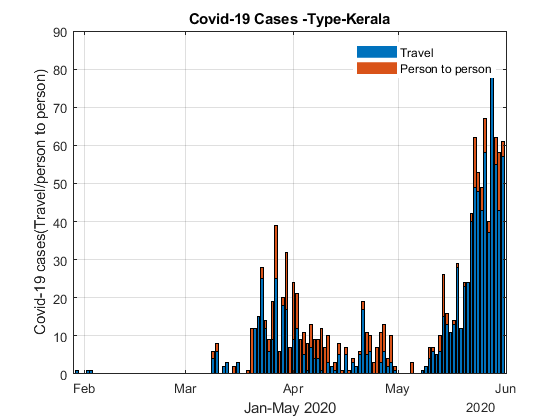

bar(j,k,'stacked')
legend("Travel","Person to person")

grid on
title('Covid-19 Cases -Type-Kerala')
xlabel('Jan-May 2020')
ylabel('Covid-19 cases(Travel/person to person)')

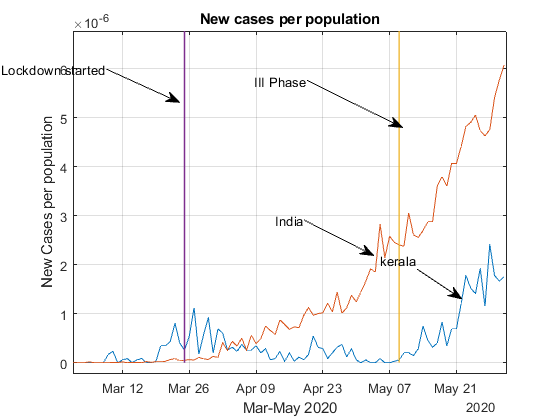


% New  cases per population
plot(t4.Date,t4.ker_newcase_popul)
hold on
plot(t4.Date,t4.india_newcase_popul)
t2mark=datetime(2020,05,09);
plot([t2mark t2mark], ylim,"LineWidth",1);
t3mark=datetime(2020,03,25);
plot([t3mark t3mark], ylim,"LineWidth",1);


hold off
grid on
xlim([datetime(2020,03,01,14,44,29)...
      datetime(2020,5,31,14,44,29)])
ylim([-0.00000023 0.00000677])
xlabel('Mar-May 2020')
ylabel('New Cases per population')

title('New cases per population')
annotation('textarrow',[0.7449 0.8245],[0.3592 0.2884],'String','kerala')
annotation('textarrow',[0.5429 0.6673],[0.4762 0.3918],'String','India')
annotation('textarrow',[0.549 0.7184],[0.8082 0.6966],'String','III Phase')
annotation('textarrow',[0.1898 0.3204],[0.8354 0.7565],'String','Lockdown started')

%import table 13
t13= readtable("C:\Users\HP\Desktop\Data csv\data 2\kerala_rehabilation_for_homeless_1.csv" );

%Rehabilitation done for homeless
t13;

t13 = 31×4 table
       Date       Corporations_Muncipality    GramaPanchayats    Total
    __________    ________________________    _______________    _____

    03/26/0020              1331                      0          1331 
    03/27/0020               763                    290          1053 
    03/28/0020              2162                    407          2569 
    03/29/0020              2162                    350          2512 
    03/30/0020              2162                    407          2569 
    03/31/0020              2162                    498          2660 
    04/01/0020              2329                    611          2940 
    04/02/0020              2317                    444          2761 
    04/03/0020              2320                    486          2806 
    04/04/0020              2321                    489          

l=[t13.Date];

l = 31×1 datetime array
   03/26/0020
   03/27/0020
   03/28/0020
   03/29/0020
   03/30/0020
   03/31/0020
   04/01/0020
   04/02/0020
   04/03/0020
   04/04/0020
   04/05/0020
   04/06/0020
   04/07/0020
   04/08/0020
   04/09/0020
   04/10/0020
   04/11/0020
   04/12/0020
   04/13/0020
   04/14/0020
   04/15/0020
   04/16/0020
   04/17/0020
   04/18/0020
   04/19/0020
   04/20/0020
   04/21/0020
   04/22/0020
   04/23/0020
   04/24/0020


m=[t13.Corporations_Muncipality,t13.GramaPanchayats];

m =         1331           0
         763         290
        2162         407
        2162         350
        2162         407
        2162         498
        2329         611
        2317         444
        2320         486
        2321         489


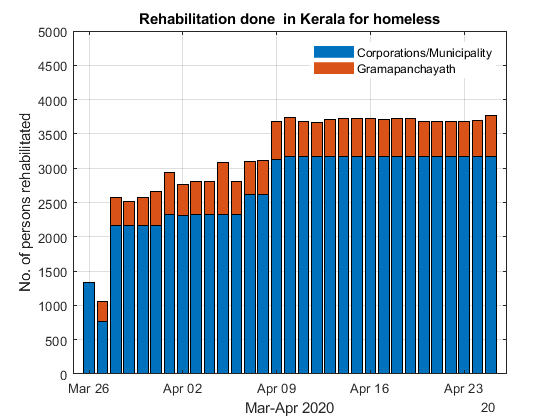

bar(l,m,'stacked')

xlim([datetime(20,3,24,19,12,0)...
      datetime(20,4,26,4,48,0)])
ylim([0 5000])
title('Rehabilitation done  in Kerala for homeless')
xlabel('Mar-Apr 2020')
ylabel('No. of persons rehabilitated')

grid on
legend("Corporations/Municipality","Gramapanchayath")

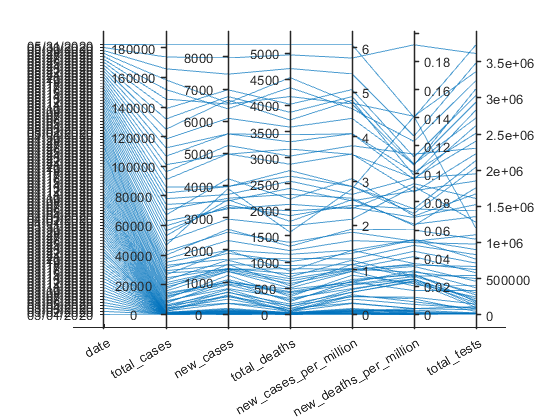

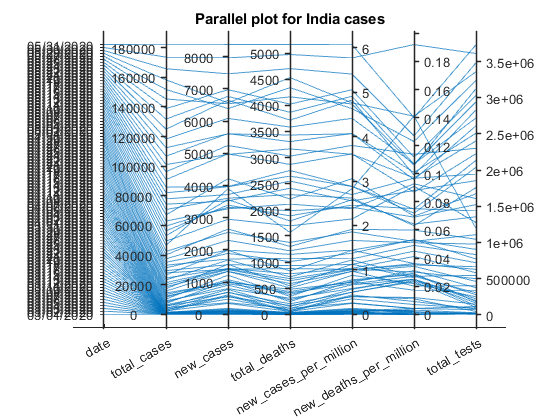

%Parallel plot for India
t19= readtable("C:\Users\HP\Desktop\Data csv\data 2\India_1.csv" );
parallelplot(t19)
title('Parallel plot for India cases')

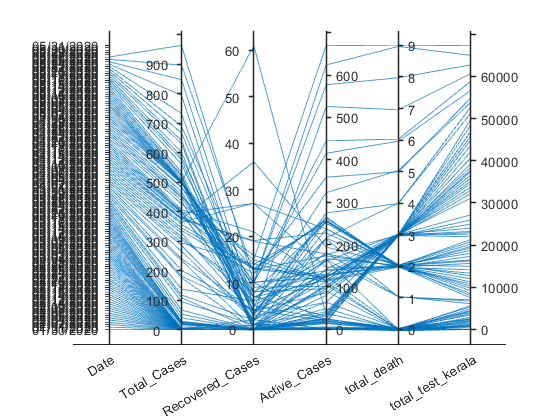

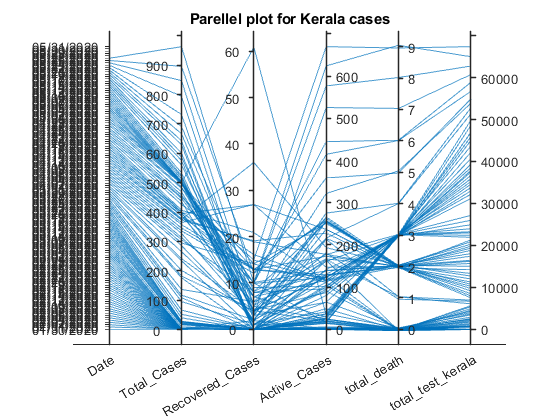

%Parallel plot for Kerala
t20= readtable("C:\Users\HP\Desktop\Data csv\data 2\Kerala Cases_1.csv" );
parallelplot(t20)
title('Parellel plot for Kerala cases')

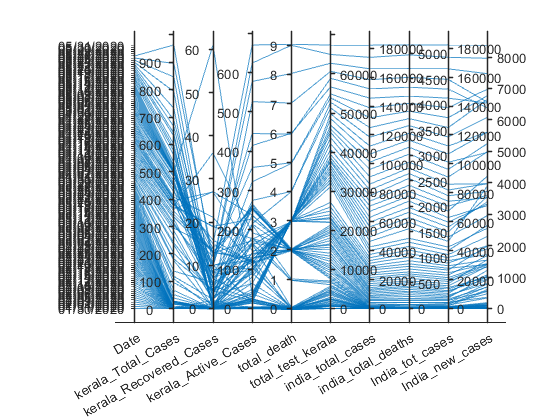

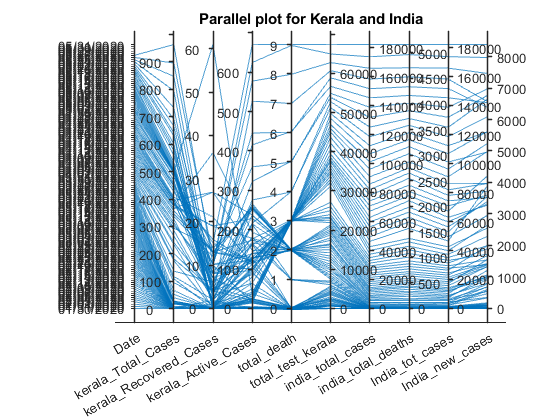

%Parallel plot for India and kerala combined
t21= readtable("C:\Users\HP\Desktop\Data csv\data 2\Kerala Cases_India_Cases_merged_1.csv" );
parallelplot(t21)

title('Parallel plot for Kerala and India')

%Community kitchen
t22= readtable("C:\Users\HP\Desktop\Data csv\data 2\11223344.csv" );

t22

t22 = 49×5 table
       Date       Individual_served    FreeMeals     PaidMeals    Homedelivery
    __________    _________________    __________    _________    ____________

    05/17/2020            38648             29150       9498            24932 
    05/16/2020            38648             29150       9498            24932 
    05/15/2020            75124             58526      16598            55504 
    05/14/2020            75912             58860      17052            31014 
    05/13/2020            76908             60192      16716            57681 
    05/12/2020            78782             62112      16670            59270 
    05/11/2020            79989             63951      16038            60155 
    05/10/2020            76349             64025      12324            61375 
    05/09/2020        

x=[t22.Date]

x = 49×1 datetime array
   05/17/2020
   05/16/2020
   05/15/2020
   05/14/2020
   05/13/2020
   05/12/2020
   05/11/2020
   05/10/2020
   05/09/2020
   05/08/2020
   05/07/2020
   05/06/2020
   05/05/2020
   05/04/2020
   05/03/2020
   05/02/2020
   05/01/2020
   04/30/2020
   04/29/2020
   04/28/2020
   04/27/2020
   04/26/2020
   04/25/2020
   04/24/2020
   04/23/2020
   04/22/2020
   04/21/2020
   04/20/2020
   04/19/2020
   04/18/2020


y=[t22.Individual_served,t22.FreeMeals,t22.PaidMeals,t22.Homedelivery]

y =        38648       29150        9498       24932
       38648       29150        9498       24932
       75124       58526       16598       55504
       75912       58860       17052       31014
       76908       60192       16716       57681
       78782       62112       16670       59270
       79989       63951       16038       60155
       76349       64025       12324       61375
       76349       64025       12324       61375
      100407       85435       17972       75130


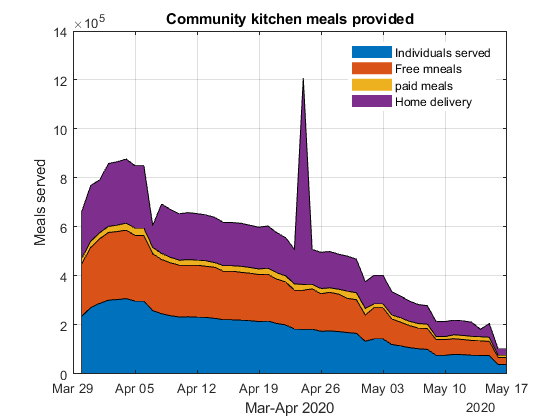



area(x,y)
legend("Individuals served","Free mneals","paid meals","Home delivery")

grid on
title('Community kitchen meals provided')
xlabel('Mar-Apr 2020')
ylabel('Meals served')